# Peridynamics 2D Conduction Thermal Simulation with Crack

Problem Simulated:

Convention used:   x$\to$is Length and y$\uparrow$is width. Origin of domain is at Point A.

(Plate with crack)

D -------------------------------------------------- C $\uparrow$

   |                                                           |     |

   |                                                           |     |

   |                 -------------------                   |     |  W

   |                 $\longleftarrow -2a-\to$                   |     |

   |                                                           |     |

A -------------------------------------------------- B $\downarrow$


$$\longleftarrow -------\;L-------\to$$


## Custom Functions List

- generate_node_locations - This function is used to generate the node locations as an array in the domain.

- initialize_initial_temperature - This function is used to update the temperature array from the boundary conditions

- find_nodes_within_horizon - This function is used to find the nodes which are inside the specified horizon

- generate_interaction_id - This function is used to compute the interaction ids for the elements in the domain

- compute_cross_product: This function is used to find the cross product between two vector

- remove_nodes_in_crack_from_horizon: This function is used to create a flag cell to include/neglect the interaction

- apply_essential_boundary_condition_to_solver: This function is used to apply the essential boundary condition to the solver

% Clear the variables initialized before
clear global;
clc;clear;

SimFold='thermal_crack_2d'; % Create a new folder to store the required workspace variables and vtk files

## Define the required Properties

**Physical properties**

domain_length = 20e-2; % Length of the domain (m)
domain_width = 20e-2; % Width of domain (m)

% Crack Definition
crack_starting_point = [0.5,1] * 10e-2; % (x,y) cordinates of the Starting point of the crack
crack_ending_point = [1.5,1] * 10e-2; % (x,y) cordinates of the End points of the crack

number_of_nodes_length = 21; % Number of nodes in the length of domain
number_of_nodes_width = 21; % Number of nodes in the width of domain

no_of_neighbours = 3.015; % Number of neighbours (which can be changed by user)
thickness = 1e-2; %Thickness of plate in (m)

**Simulation properties**

dt = 1; % Timesteps
t0 = 0; % Starting time
tf = 500; % Ending time 
time_array = t0 : dt : tf; % Array with all time values from start to end

% custom function to generate node locations in the domain
[domain,dx,dy] = generate_node_locations(domain_length, number_of_nodes_length, domain_width, number_of_nodes_width); 

% Horizon Length for the Simulation (Horizon radius assuming circular horion)
horizon_radius = no_of_neighbours * dy;

r = domain_width/(2 * number_of_nodes_width); % Term used for volume correction calculation

% Tolerance value to stop the iteration
tolerance = 1e-10;

% Elemental volume = (L*W*thickness)/(number of nodes)
elemental_volume = (domain_width * domain_length * thickness)/(length(domain));

**Thermal properties**

material_density = 2800; % Density in kg/m^3
material_macro_thermal_conductivity = 200; % K of material 
material_specific_heat_capacity = 1000; % Cp value of material

%Thermal diffusivity of material 


$$\alpha =\frac{\kappa }{\rho C_p }$$


material_thermal_diffusivity = material_macro_thermal_conductivity/ material_density/material_specific_heat_capacity;

micro_thermal_conductivity = 6 * material_macro_thermal_conductivity/ (thickness * horizon_radius^3 * 3.141);

% Initialize Temperature of domain to 0 degrees @ t= 0
% Temperature_of_domain = zeros(length(domain),1);
Temperature_of_domain = ones(length(domain),1) * 500;

**Boundary Conditions**

At t=0, T(x,y) == 0

At t>0, T along AB = -100 & At T along DC = 100 

D -------------------------------------------------- C $\uparrow$

   |                                                           |     |

   |                                                           |     |

   |                 -------------------                   |     |  W

   |                 $\longleftarrow -2a-\to$                   |     |

   |                                                           |     |

A -------------------------------------------------- B $\downarrow$


$$\longleftarrow -------\;L-------\to$$


global essential_boundary_condition_nodes;
% Initialize variable to speed up calculations
essential_boundary_condition_nodes = zeros(2*number_of_nodes_length,1);

for node = 1 : number_of_nodes_length
    essential_boundary_condition_nodes(node) = node;
    essential_boundary_condition_nodes(node + number_of_nodes_length) = (length(domain) - number_of_nodes_length) + node;
end

% Applying boundary condition for temperature
for i = 1 : length(essential_boundary_condition_nodes)
    if (i <= number_of_nodes_length)
        Temperature_of_domain(essential_boundary_condition_nodes(i)) = -100; % T along AB = -100
    else
        Temperature_of_domain((essential_boundary_condition_nodes(i))) = 100; % T along DC = 100
    end    
end

% Find the neighbouring nodes of the given element
[neighbours_of_element] = find_nodes_within_horizon(domain,horizon_radius);

% Generate the interaction ids for the elements in the domain
[interaction_id] = generate_interaction_id_matrix(domain, neighbours_of_element);

total_number_of_interactions = length(interaction_id);

% Generate a flag vector which stores 1(True) if interaction doesn't cross
% crack and 0 (False) if interaction crosses crack
[interaction_crossing_crack_flag_vector] = find_interactions_crossing_crack_in_domain(domain,interaction_id, ...
                                                                                crack_starting_point,crack_ending_point);

## Volume Correction for interactions:

% Initialize variables to speed up calculations
volume_correction = zeros(total_number_of_interactions,1);
distance_of_interaction = zeros(total_number_of_interactions,1);

for interaction = 1 : total_number_of_interactions
    node_position = domain(interaction_id(interaction,1),:); % position of kth node
    neighbour_position = domain(interaction_id(interaction,2),:); % position of jth node
    
    % If interaction crossing crack, then initalize volume correction to
    % zero and distance as 1 (distance can't be made 0 because it is in
    % denominator so substituting dummy value of 1, anyways the contributing term becomes 0 since it's
    % multiplied by volume correction term (=0).
    if interaction_crossing_crack_flag_vector(interaction) == 0
        distance = 1;
        volume_correction(interaction) = 0;
    else
        distance = norm(node_position - neighbour_position);
    
        if distance >= horizon_radius - r && distance <= horizon_radius
            volume_correction(interaction) = (horizon_radius + r - distance)/2/r;  
        else
            volume_correction(interaction) = 1;
        end
    end
    
    distance_of_interaction(interaction) = distance;
    
end

## Surface Correction for interactions:

% Initialize variables to speed up calculations
surface_correction = zeros(total_number_of_interactions,1);
counter = 1;
Temp_to_compute_surface_correction = zeros(length(domain),1);

for i = 1 : length(domain)    
    LT = domain(i,:);
    Temp_to_compute_surface_correction(counter) = sum(LT);
    counter = counter + 1;
end

Z_k = zeros(length(domain),1);
Z_classical = ones(length(domain),1) * material_macro_thermal_conductivity;

for interaction = 1 : total_number_of_interactions
    Lid = interaction_id(interaction,:);
    current_node = Lid(2); % position of kth node 
    neighbour_node = Lid(1); % position of jth node
    
    Z_k(current_node) = Z_k(current_node) + .5*.5*micro_thermal_conductivity * volume_correction(interaction) *...
            (Temp_to_compute_surface_correction(neighbour_node)-Temp_to_compute_surface_correction(current_node))^2 ...
                * elemental_volume/distance_of_interaction(interaction); % Eq.12.90 &, 12.56, 12.53       
end

Nodal_surf_corr = Z_classical ./ Z_k;

for interaction = 1 : total_number_of_interactions
    Lid = interaction_id(interaction,:);
    current_node = Lid(2);
    neighbour_node = Lid(1);
    
    surface_correction(interaction) = .5 * (Nodal_surf_corr(current_node) + Nodal_surf_corr(neighbour_node)); 
end

## Solver (Implicit Solver)

AX = B solution for the discretised governing equation

Netwon Raphson Method to solve the system of equations AX = B

% Initialize variables to speed up the calculations
A = -eye(length(domain));
f = -ones(length(domain),1).* Temperature_of_domain;
b = zeros(length(domain),1);

m = 6 * material_thermal_diffusivity * dt/ thickness/ horizon_radius^3 /3.141;

for interaction = 1 : total_number_of_interactions
    current_node = interaction_id(interaction,2);
    neighbour_node = interaction_id(interaction,1);
    
    A(current_node, neighbour_node) = A(current_node, neighbour_node) + volume_correction(interaction) * ...
                    elemental_volume * m * interaction_crossing_crack_flag_vector(interaction)  ...
                                                * surface_correction(interaction)/distance_of_interaction(interaction);
    
    A(current_node, current_node) = A(current_node, current_node) - volume_correction(interaction) *  ...
                    elemental_volume * m * interaction_crossing_crack_flag_vector(interaction) ...
                                                * surface_correction(interaction)/distance_of_interaction(interaction);        
end
[A1,f] = apply_essential_boundary_condition_to_solver(A,f);

for time = 2 : dt : length(time_array)
    normalized_error = 1;
    current_time = 0;
    while normalized_error > tolerance
        
        b = f - A * Temperature_of_domain;
        [A1,b1] = apply_essential_boundary_condition_to_solver(A,b);
        
        dT = linsolve(A1,b1);
        Temperature_of_domain = Temperature_of_domain + dT;
        normalized_error = dT' * dT;
        
        current_time = current_time + 1;
    end
    
    f = -Temperature_of_domain; 

    vtkwrite(append(SimFold,'\temp_profile_',num2str(time), '.vtk'),'structured_grid', domain(:,1), domain(:,2), ...
                                    zeros(length(domain),1),'scalars','Temperature',Temperature_of_domain);
end
save(('final_Temp_values.mat'),'Temperature_of_domain');

### Code to check the Temperature values with the working code:

Because, the previous code saves T values coloumn wise, and this code saves T values row wise,

                the present T values have been copied to a new variable which saves T as coloumn wise so that the difference in T values from the 

                different codes can be calculated easily.

T_to_check = zeros(length(domain),1);

for i = 1: number_of_nodes_length
    
    for j = 1 : number_of_nodes_width
        T_to_check(j + (i - 1) * number_of_nodes_width,:) = Temperature_of_domain((j - 1) * number_of_nodes_length + i,:);
    end
    
end

Plot the temperature Variation along y axis and x = 0

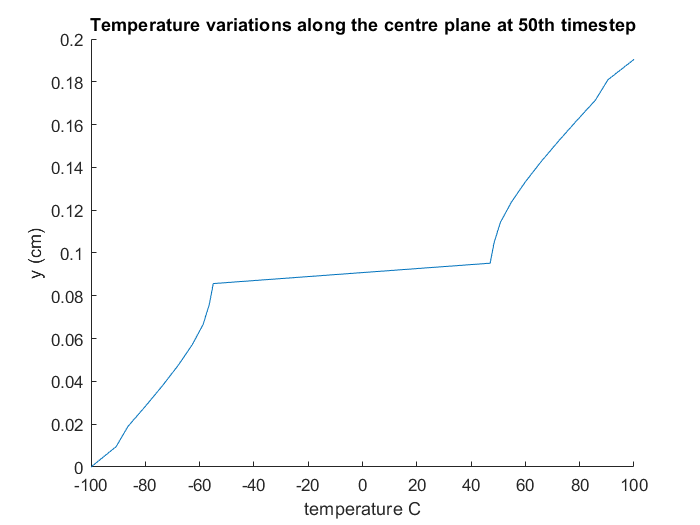

figure;
hold on;
y_axis_values = zeros(1, number_of_nodes_width);
y_position = 0;
for i = 1 : number_of_nodes_width
    y_axis_values(i) = y_position;
    y_position = y_position + dy;
end
ylabel('y (cm)');
xlabel('temperature C');
title('Temperature variations along the centre plane at 50th timestep');
% plot(T_to_check(1301:1350,:), y_axis_values);
plot(T_to_check(211:231,:), y_axis_values);

% plot(T_to_check(56:66,:), y_axis_values);

## Custom function definitions

- Generate node locations: This function sets the node locations of the elements in the domain.

function [domain,dx,dy] = generate_node_locations(domain_length, number_of_nodes_length, ...
                            domain_width, number_of_nodes_width) % Function to generate the spatial location of the nodes
    
    dx = domain_length/number_of_nodes_length;
    dy = domain_width/number_of_nodes_width;
    
    %Array is stored row-wise meaning 1st number_of_nodes_length are
    % co-ordiantes of 1st row
    
    % Initialize array to speed up calculations
    total_number_of_nodes = number_of_nodes_width * number_of_nodes_length;
    domain = zeros(total_number_of_nodes,2);
    
    % Iterator to loop through the iterations
    current_node = 1;
    
    for coloumn = 1 : number_of_nodes_length
        for row  = 1 : number_of_nodes_width
            domain(current_node,:) = [dx*row, dy*coloumn];
            current_node = current_node + 1;
        end
    end
    
end

         3. find_nodes_within_horizon: This function is used to find the node values which are within the specifed horizon

function [neighbours_of_element] = find_nodes_within_horizon(domain,horizon_radius)
    
    % Initialize variable to speed up calculations
    neighbours_of_element = cell(length(domain),1);
    
    for element = 1 : length(domain)
        
        % Store the current value in the temporary variable
        x_node = domain(element,1);
        y_node = domain(element,2);
        
        % find the distance between the vectors and current vector
        distance = sqrt((domain(:,1) - x_node).^2 + (domain(:,2) - y_node).^2);
       
        neighbour_indices = find(distance <= horizon_radius); % Store the neighbour indices in an array 
 
        neighbour_indices(neighbour_indices == element) = []; % Remove the self id node from the list
        
        neighbours_of_element{element} = neighbour_indices';
    end
    
end

         4. generate_interaction_id: This function is used to create the interaction matrix for the domain:

             The matrix is such that first element is j (neighbour) and second element is k (current node)

function [interaction_id] = generate_interaction_id_matrix(domain,neighbours_of_element)
    
    iterator = 1; % Just a temporary iterator for the cummulative interaction id
    
    for current_node = 1 : length(domain)
        for neighbours = 1 : length(neighbours_of_element{current_node})
            interaction_id(iterator,:) = [neighbours_of_element{current_node}(neighbours) current_node];
            iterator = iterator + 1;
        end
    end
end

         5. compute_cross_product: This function is used to find the cross product between two vector

function [cross_product] = compute_cross_product(point1, point2)
    cross_product = point1(1) * point2(2) - point1(2) * point2(1);
end

         6. remove_nodes_in_crack_from_horizon: This function is used to create a flag cell to include/neglect the interaction:

            Consider the crack initial position vector as $\vec{a}
$ and the crack end position as $\vec{b}$

            The line equation in vector form of the 2 points $\vec{a}$ and $\vec{b}$ is given by $\vec{r}$= $\vec{a}$ + k ($\vec{b} - \vec{a}
$)  where k $\epsilon$ $\Re$

            Conside the current node position vector as $\vec{p}$ and the interaction node neighbour position vector as $\vec{q}$

            The line equation in vector form of the 2 points $\vec{p}$ and $\vec{q}$ is given by $\vec{r}$= $\vec{p}$ + t ( $\vec{q}$ -  $\vec{p}$) where t $\epsilon$ $\Re$

            The point of intersection of the two lines can be found by equating the $\vec{r}$ for both the lines i.e. $\vec{p}$ + t ( $\vec{q}$ -  $\vec{p}$) = $\vec{a}$ + k ($\vec{b} - \vec{a}
$)

            Since there are 2 unknowns, inorder to eliminate one of the equations, e.g. taking cross product of ( $\vec{q}$ -  $\vec{p}$) on both sides eliminates t.

            Similarly, taking cross product of ($\vec{b} - \vec{a}
$) on both sides eliminates k.

            The point of intersection lies inbetween the lines if & only if $0\le k \leq 1$ and $0\le t \leq 1$.

             The matrix is such that first element is j (neighbour) and second element is k (current node)

function [interaction_crossing_crack_flag_vector] = find_interactions_crossing_crack_in_domain(domain, ...
                                                        interaction_id,crack_starting_point,crack_ending_point)
    
    % Line equation of crack in vector form a + t (b-a) where a,b are two points
    a = [crack_starting_point(1), crack_starting_point(2)];
    
    % b is the endpoint of the crack
    b_minus_a = [crack_ending_point(1) - crack_starting_point(1), crack_ending_point(2) - crack_starting_point(2)];
                                                    
    % Initialize variable to speed up calculations
    interaction_crossing_crack_flag_vector = zeros(length(interaction_id),1);
    
    for interaction = 1 : length(interaction_id)
        point1 = [domain(interaction_id(interaction,2),1), domain(interaction_id(interaction,2),2)];
        
        point2 = [domain(interaction_id(interaction,1),1), domain(interaction_id(interaction,1),2)];
        
        % Line equation of line joining current node (q) and neighbour (s)
            s = point2 - point1;
            
            k = (compute_cross_product(a,b_minus_a) - compute_cross_product(point1, b_minus_a))/...
                                                                    compute_cross_product(s,b_minus_a); 
            
            t = (compute_cross_product(point1,s) - compute_cross_product(a,s))/compute_cross_product(b_minus_a,s);
            
            if and(and(t >= 0, t <= 1), and(k >= 0, k <= 1))
                interaction_crossing_crack_flag_vector(interaction) = 0;
            else
                interaction_crossing_crack_flag_vector(interaction) = 1;
            end
    end
    
end

         7. apply_essential_boundary_condition_to_solver: This function is used to apply the essential boundary condition to the solver

function [A1,b1] = apply_essential_boundary_condition_to_solver(A,b)
    global essential_boundary_condition_nodes;
    
    A1 = A;
    b1 = b;
    if(~isempty(essential_boundary_condition_nodes))
        for i = 1 : length(essential_boundary_condition_nodes)
            nid = essential_boundary_condition_nodes(i);
            A(:,nid) = 0;
            A(nid,:) = 0;
            A(nid,nid) = 1;
            b(nid,1) = 0;
        end
    else
        return;
    end
    
    A1 = A;
    b1 = b;
end
